%% Lista 01 - Introdução ao MATLAB - SEL0359 - Controle Digital %% 

%% Prof. Dr. Marcos Rogério Fernandes %% 

%% Nome: Vitor Augusto Tibério - 14658834 - Eng. Elétrica - EESC/USP

clear ; clc ; close all

%% Exercício 01: Elabore um programa para calcular os 100 primeiros termos da sequência de Fibonacci e 
%% plote o resultado usando a função stem%%

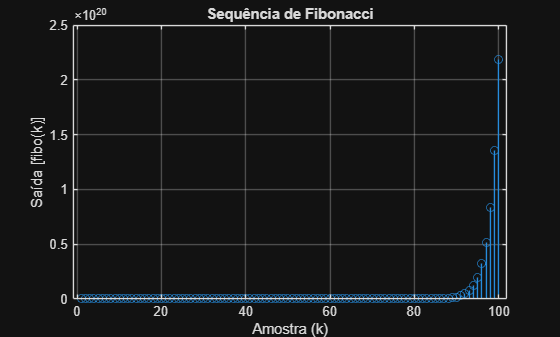

N = 100; 
fibo = zeros(1,N); 
fibo(1) = 0; 
fibo(2) = 1;

for n  = 3:N
    fibo(n) = fibo(n-1) + fibo(n-2);
end 
stem(fibo);
grid on ;
xlabel('Amostra (k)');
ylabel('Saída [fibo(k)]');
title('Sequência de Fibonacci');

%%Exercício 02 %%

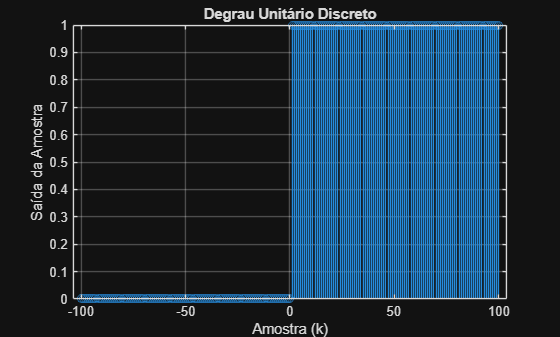

% Degrau Unitário % 

N = 100; 
k = -N:N; 
uni = k > 0; 
stem(k, uni);
grid on 
xlabel('Amostra (k)')
ylabel('Saída da Amostra')
title('Degrau Unitário Discreto')

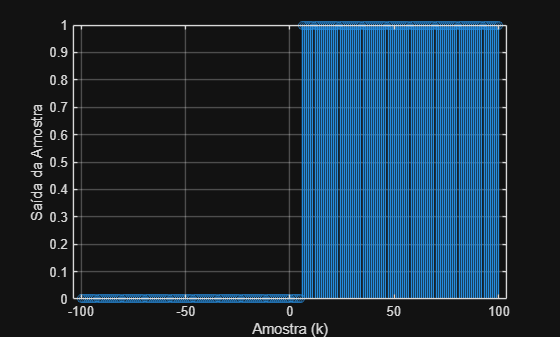

% Retangulo unitário de janela 5 % 

N = 100; 
k = -N:N; 
uni = k > 5; 
stem(k, uni)
grid on 
xlabel('Amostra (k)')
ylabel('Saída da Amostra')

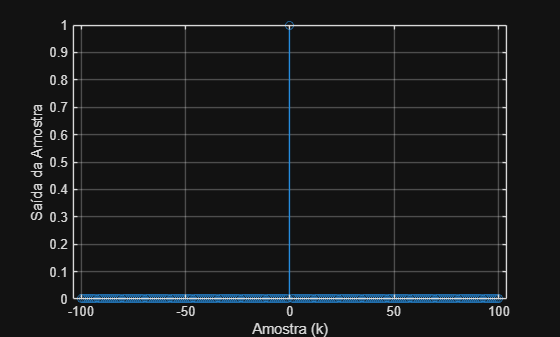

% Função Impulso %
N = 100; 
k = -N:N; 
imp = k == 0; 
stem(k, imp)
grid on 
xlabel('Amostra (k)')
ylabel('Saída da Amostra')

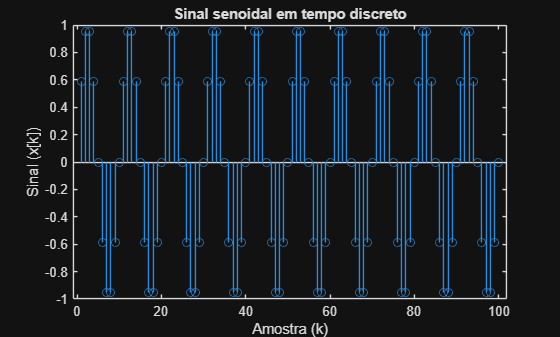

% Função Seno %

Ts = 0.1; 
A = 1; 
w = 2*pi*1;
phi = 0; 
N = 100; 
k = 1:N; 
x = A*sin(w*k*Ts+phi);
figure;
stem(x);
xlabel('Amostra (k)');
ylabel('Sinal (x[k])');
title('Sinal senoidal em tempo discreto');

% Função Sinc %  
N = 100; 
k = 1:N; 
x = sinc(k)

x = 1.0e-15 *

    0.0390   -0.0390    0.0390   -0.0390    0.0390   -0.0390    0.0390   -0.0390    0.0390   -0.0390    0.1418   -0.0390   -0.0480   -0.0390    0.1144   -0.0390   -0.0275   -0.0390    0.0985   -0.0390   -0.0149   -0.1418    0.0881   -0.0390   -0.0063    0.0480    0.0809   -0.0390   -0.0000   -0.1144    0.0755   -0.0390    0.0047    0.0275    0.0713   -0.0390    0.0084   -0.0985    0.0680   -0.0390    0.1217    0.0149    0.0653   -0.1418    0.0139   -0.0881   -0.0332   -0.0390    0.1082    0.0063


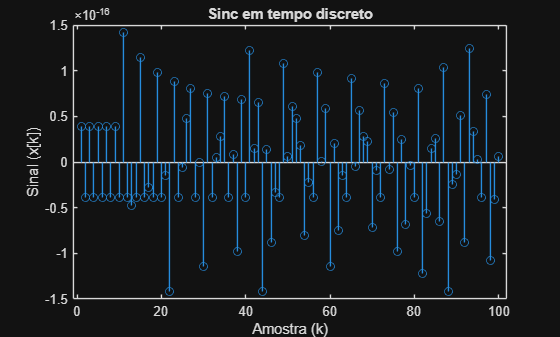

figure;
stem(k, x);
xlabel('Amostra (k)');
ylabel('Sinal (x[k])');
title('Sinc em tempo discreto');

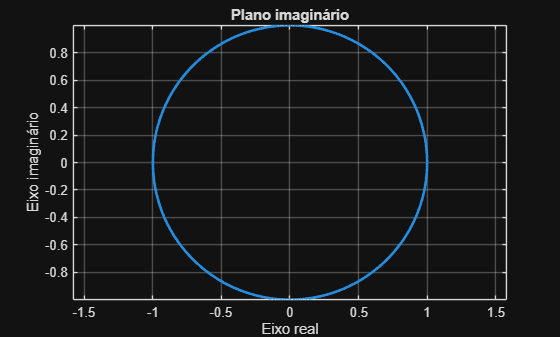

% Exercício 03 % 

theta=0:0.01:2*pi;
x=exp(1j*theta);
figure
plot(real(x),imag(x),'linewidth',2)
grid on
xlabel('Eixo real')
ylabel('Eixo imaginário')
title('Plano imaginário')
axis equal

% Exercício 04 % 

p1 = [5 3 10 9]; 
p2 = [0 15 4 7]; 
p1_p2 = conv(p1, p2)

p1_p2 =      0    75    65   197   196   106    63



% Portando, conclui-se que p1(x)p2(x) = 75x^5 + 65x^4 + 197x^3 + 106x + 63

% Exercício 05 % 

z = tf('z')


z =
 
  z
 
Sample time: unspecified
Discrete-time transfer function.


G = (0.02268*z + 0.02052)/((z-0.7408)*(z-1))


G =
 
   0.02268 z + 0.02052
  ----------------------
  z^2 - 1.741 z + 0.7408
 
Sample time: unspecified
Discrete-time transfer function.



figure 
Gf = feedback(G,1) %função de transferência em malha fechada com realimentação unitária


Gf =
 
   0.02268 z + 0.02052
  ----------------------
  z^2 - 1.718 z + 0.7613
 
Sample time: unspecified
Discrete-time transfer function.
